% Plotting kdf of mass losses across sites 
% Upload file to read into matlab 
VolChange = readtable('Individual_V_change_Tsaiwei.csv');

% Now isolate rows of data by formation 
%shoutout tsaiwei for formatting this so I didn't have 
%to go from raw data through my script a bunch :)
Lower_Mugi = table2array(VolChange(1,:));
Upper_Mugi = table2array(VolChange(2,:));
Kure = table2array(VolChange(3,:));
Ghost = table2array(VolChange(4,:));
Kodiak = table2array(VolChange(5,:));
Okitsu = table2array(VolChange(6,:));
Hyuga = table2array(VolChange(7,:));
Uyak = table2array(VolChange(8,:));
Makimine = table2array(VolChange(9,:));
Sanbagawa = table2array(VolChange(10,:));

% KDF function for each group
[LM_ML, LM_f] = ksdensity(Lower_Mugi)

LM_ML =     0.0000    0.0001    0.0001    0.0001    0.0002    0.0003    0.0003    0.0005    0.0006    0.0008    0.0010    0.0012    0.0015    0.0018    0.0022    0.0026    0.0030    0.0034    0.0039    0.0043    0.0047    0.0052    0.0056    0.0059    0.0063    0.0066    0.0069    0.0072    0.0074    0.0077    0.0081    0.0084    0.0089    0.0095    0.0101    0.0110    0.0119    0.0131    0.0143    0.0158    0.0173    0.0190    0.0208    0.0226    0.0244    0.0262    0.0279    0.0294    0.0308    0.0320


LM_f =   -73.4689  -72.7006  -71.9324  -71.1641  -70.3958  -69.6276  -68.8593  -68.0911  -67.3228  -66.5545  -65.7863  -65.0180  -64.2498  -63.4815  -62.7132  -61.9450  -61.1767  -60.4085  -59.6402  -58.8719  -58.1037  -57.3354  -56.5672  -55.7989  -55.0306  -54.2624  -53.4941  -52.7259  -51.9576  -51.1893  -50.4211  -49.6528  -48.8846  -48.1163  -47.3480  -46.5798  -45.8115  -45.0433  -44.2750  -43.5067  -42.7385  -41.9702  -41.2020  -40.4337  -39.6654  -38.8972  -38.1289  -37.3607  -36.5924  -35.8241


LM_ML_n = (LM_ML./sum(LM_ML))*10

LM_ML_n =     0.0003    0.0005    0.0007    0.0010    0.0014    0.0019    0.0026    0.0035    0.0046    0.0059    0.0075    0.0094    0.0116    0.0141    0.0168    0.0198    0.0230    0.0263    0.0297    0.0331    0.0364    0.0396    0.0427    0.0455    0.0482    0.0506    0.0528    0.0550    0.0571    0.0594    0.0619    0.0649    0.0684    0.0727    0.0779    0.0842    0.0916    0.1003    0.1102    0.1212    0.1333    0.1462    0.1598    0.1736    0.1875    0.2011    0.2141    0.2261    0.2368    0.2460


[UM_ML, UM_f] = ksdensity(Upper_Mugi)

UM_ML =     0.0002    0.0003    0.0005    0.0007    0.0011    0.0016    0.0023    0.0032    0.0044    0.0059    0.0077    0.0099    0.0124    0.0151    0.0181    0.0212    0.0243    0.0273    0.0300    0.0324    0.0343    0.0356    0.0364    0.0366    0.0362    0.0353    0.0341    0.0326    0.0310    0.0293    0.0276    0.0260    0.0246    0.0233    0.0222    0.0212    0.0203    0.0194    0.0186    0.0177    0.0168    0.0159    0.0150    0.0141    0.0132    0.0124    0.0117    0.0110    0.0104    0.0100


UM_f =  -113.0612 -112.2088 -111.3565 -110.5041 -109.6518 -108.7994 -107.9471 -107.0947 -106.2424 -105.3901 -104.5377 -103.6854 -102.8330 -101.9807 -101.1283 -100.2760  -99.4236  -98.5713  -97.7189  -96.8666  -96.0142  -95.1619  -94.3095  -93.4572  -92.6048  -91.7525  -90.9002  -90.0478  -89.1955  -88.3431  -87.4908  -86.6384  -85.7861  -84.9337  -84.0814  -83.2290  -82.3767  -81.5243  -80.6720  -79.8196  -78.9673  -78.1149  -77.2626  -76.4103  -75.5579  -74.7056  -73.8532  -73.0009  -72.1485  -71.2962


UM_ML_n = (UM_ML./sum(UM_ML))*10

UM_ML_n =     0.0016    0.0026    0.0040    0.0062    0.0093    0.0137    0.0196    0.0275    0.0377    0.0504    0.0659    0.0843    0.1054    0.1289    0.1543    0.1807    0.2072    0.2326    0.2560    0.2762    0.2923    0.3038    0.3103    0.3117    0.3085    0.3013    0.2908    0.2781    0.2640    0.2495    0.2353    0.2220    0.2099    0.1990    0.1894    0.1808    0.1729    0.1655    0.1582    0.1509    0.1435    0.1358    0.1281    0.1204    0.1129    0.1058    0.0994    0.0938    0.0890    0.0852


[Ku_ML, Ku_f] = ksdensity(Kure)

Ku_ML =     0.0000    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0007    0.0008    0.0011    0.0013    0.0016    0.0019    0.0023    0.0028    0.0033    0.0038    0.0045    0.0051    0.0058    0.0066    0.0073    0.0081    0.0089    0.0097    0.0105    0.0113    0.0120    0.0127    0.0134    0.0140    0.0145    0.0150    0.0154    0.0158    0.0161    0.0163    0.0165    0.0166    0.0167    0.0167    0.0168    0.0167    0.0167    0.0167    0.0166    0.0165


Ku_f =  -124.1300 -122.7920 -121.4541 -120.1161 -118.7781 -117.4401 -116.1021 -114.7642 -113.4262 -112.0882 -110.7502 -109.4122 -108.0743 -106.7363 -105.3983 -104.0603 -102.7223 -101.3844 -100.0464  -98.7084  -97.3704  -96.0324  -94.6945  -93.3565  -92.0185  -90.6805  -89.3425  -88.0046  -86.6666  -85.3286  -83.9906  -82.6526  -81.3147  -79.9767  -78.6387  -77.3007  -75.9627  -74.6248  -73.2868  -71.9488  -70.6108  -69.2728  -67.9349  -66.5969  -65.2589  -63.9209  -62.5829  -61.2450  -59.9070  -58.5690


Ku_ML_n = (Ku_ML./sum(Ku_ML))*10

Ku_ML_n =     0.0005    0.0007    0.0010    0.0013    0.0018    0.0024    0.0032    0.0042    0.0054    0.0070    0.0090    0.0113    0.0141    0.0175    0.0215    0.0261    0.0314    0.0373    0.0441    0.0515    0.0596    0.0684    0.0778    0.0877    0.0980    0.1086    0.1194    0.1302    0.1408    0.1512    0.1611    0.1706    0.1794    0.1874    0.1946    0.2011    0.2066    0.2113    0.2151    0.2182    0.2205    0.2222    0.2233    0.2240    0.2242    0.2240    0.2236    0.2229    0.2221    0.2211


[G_ML, G_f] = ksdensity(Ghost)

G_ML =     0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0010    0.0015    0.0021    0.0029    0.0039    0.0051    0.0065    0.0081    0.0099    0.0119    0.0140    0.0161    0.0181    0.0200    0.0218    0.0233    0.0245    0.0254    0.0259    0.0260    0.0258    0.0253    0.0245    0.0234    0.0221    0.0207    0.0192    0.0177    0.0162    0.0148    0.0134    0.0122    0.0111    0.0101    0.0092    0.0084    0.0076    0.0069    0.0063    0.0058    0.0053    0.0050    0.0047    0.0045


G_f =  -121.0828 -119.7088 -118.3348 -116.9608 -115.5868 -114.2128 -112.8388 -111.4648 -110.0908 -108.7168 -107.3428 -105.9688 -104.5948 -103.2208 -101.8468 -100.4728  -99.0988  -97.7248  -96.3509  -94.9769  -93.6029  -92.2289  -90.8549  -89.4809  -88.1069  -86.7329  -85.3589  -83.9849  -82.6109  -81.2369  -79.8629  -78.4889  -77.1149  -75.7409  -74.3669  -72.9929  -71.6189  -70.2449  -68.8709  -67.4970  -66.1230  -64.7490  -63.3750  -62.0010  -60.6270  -59.2530  -57.8790  -56.5050  -55.1310  -53.7570


G_ML_n = (G_ML./sum(G_ML))*10

G_ML_n =     0.0009    0.0015    0.0025    0.0040    0.0062    0.0095    0.0141    0.0204    0.0288    0.0396    0.0532    0.0697    0.0892    0.1116    0.1366    0.1636    0.1919    0.2207    0.2488    0.2754    0.2995    0.3201    0.3367    0.3486    0.3556    0.3576    0.3548    0.3474    0.3360    0.3212    0.3036    0.2842    0.2636    0.2428    0.2223    0.2028    0.1846    0.1679    0.1527    0.1390    0.1265    0.1151    0.1047    0.0952    0.0867    0.0794    0.0732    0.0683    0.0648    0.0625


[Ko_ML, Ko_f] = ksdensity(Kodiak)

Ko_ML =     0.0001    0.0001    0.0002    0.0003    0.0004    0.0006    0.0009    0.0013    0.0019    0.0026    0.0036    0.0048    0.0062    0.0078    0.0097    0.0118    0.0140    0.0163    0.0186    0.0208    0.0229    0.0248    0.0264    0.0278    0.0289    0.0297    0.0302    0.0304    0.0303    0.0299    0.0292    0.0283    0.0272    0.0258    0.0243    0.0227    0.0210    0.0193    0.0177    0.0162    0.0148    0.0136    0.0125    0.0115    0.0107    0.0098    0.0091    0.0083    0.0076    0.0069


Ko_f =  -118.0118 -116.8677 -115.7237 -114.5796 -113.4355 -112.2914 -111.1474 -110.0033 -108.8592 -107.7151 -106.5710 -105.4270 -104.2829 -103.1388 -101.9947 -100.8507  -99.7066  -98.5625  -97.4184  -96.2744  -95.1303  -93.9862  -92.8421  -91.6980  -90.5540  -89.4099  -88.2658  -87.1217  -85.9777  -84.8336  -83.6895  -82.5454  -81.4014  -80.2573  -79.1132  -77.9691  -76.8250  -75.6810  -74.5369  -73.3928  -72.2487  -71.1047  -69.9606  -68.8165  -67.6724  -66.5283  -65.3843  -64.2402  -63.0961  -61.9520


Ko_ML_n = (Ko_ML./sum(Ko_ML))*10

Ko_ML_n =     0.0006    0.0011    0.0018    0.0029    0.0045    0.0069    0.0104    0.0152    0.0217    0.0302    0.0411    0.0546    0.0708    0.0897    0.1112    0.1349    0.1601    0.1863    0.2125    0.2380    0.2619    0.2835    0.3024    0.3181    0.3305    0.3395    0.3451    0.3473    0.3463    0.3420    0.3346    0.3243    0.3111    0.2956    0.2781    0.2594    0.2401    0.2209    0.2025    0.1854    0.1697    0.1557    0.1433    0.1321    0.1220    0.1125    0.1036    0.0951    0.0868    0.0788


[Ok_ML, Ok_f] = ksdensity(Okitsu)

Ok_ML =     0.0001    0.0001    0.0002    0.0003    0.0005    0.0007    0.0009    0.0013    0.0018    0.0024    0.0031    0.0040    0.0051    0.0063    0.0078    0.0093    0.0110    0.0128    0.0146    0.0164    0.0181    0.0196    0.0210    0.0221    0.0229    0.0234    0.0236    0.0235    0.0231    0.0224    0.0216    0.0206    0.0196    0.0185    0.0175    0.0165    0.0156    0.0149    0.0142    0.0137    0.0133    0.0130    0.0127    0.0125    0.0122    0.0120    0.0117    0.0114    0.0110    0.0106


Ok_f =  -125.3159 -123.9879 -122.6599 -121.3319 -120.0039 -118.6759 -117.3479 -116.0199 -114.6919 -113.3639 -112.0359 -110.7079 -109.3799 -108.0519 -106.7239 -105.3959 -104.0679 -102.7399 -101.4119 -100.0839  -98.7559  -97.4279  -96.0999  -94.7719  -93.4439  -92.1159  -90.7879  -89.4599  -88.1319  -86.8039  -85.4759  -84.1479  -82.8200  -81.4920  -80.1640  -78.8360  -77.5080  -76.1800  -74.8520  -73.5240  -72.1960  -70.8680  -69.5400  -68.2120  -66.8840  -65.5560  -64.2280  -62.9000  -61.5720  -60.2440


Ok_ML_n = (Ok_ML./sum(Ok_ML))*10

Ok_ML_n =     0.0011    0.0018    0.0027    0.0041    0.0060    0.0087    0.0123    0.0172    0.0234    0.0314    0.0413    0.0533    0.0676    0.0842    0.1031    0.1239    0.1463    0.1698    0.1938    0.2175    0.2401    0.2607    0.2786    0.2933    0.3040    0.3107    0.3131    0.3115    0.3062    0.2977    0.2866    0.2738    0.2599    0.2457    0.2319    0.2190    0.2075    0.1974    0.1890    0.1821    0.1766    0.1722    0.1686    0.1654    0.1623    0.1590    0.1553    0.1510    0.1460    0.1403


[Hy_ML, Hy_f] = ksdensity(Hyuga)

Hy_ML =     0.0001    0.0001    0.0002    0.0002    0.0003    0.0005    0.0006    0.0008    0.0011    0.0014    0.0018    0.0023    0.0029    0.0036    0.0044    0.0052    0.0062    0.0072    0.0082    0.0094    0.0105    0.0116    0.0127    0.0137    0.0146    0.0154    0.0161    0.0166    0.0170    0.0173    0.0174    0.0174    0.0172    0.0169    0.0165    0.0161    0.0156    0.0150    0.0143    0.0137    0.0130    0.0123    0.0117    0.0110    0.0103    0.0097    0.0091    0.0085    0.0079    0.0074


Hy_f =  -138.3031 -136.7000 -135.0969 -133.4938 -131.8907 -130.2876 -128.6845 -127.0814 -125.4783 -123.8752 -122.2721 -120.6691 -119.0660 -117.4629 -115.8598 -114.2567 -112.6536 -111.0505 -109.4474 -107.8443 -106.2412 -104.6381 -103.0350 -101.4319  -99.8289  -98.2258  -96.6227  -95.0196  -93.4165  -91.8134  -90.2103  -88.6072  -87.0041  -85.4010  -83.7979  -82.1948  -80.5917  -78.9887  -77.3856  -75.7825  -74.1794  -72.5763  -70.9732  -69.3701  -67.7670  -66.1639  -64.5608  -62.9577  -61.3546  -59.7515


Hy_ML_n = (Hy_ML./sum(Hy_ML))*10

Hy_ML_n =     0.0013    0.0019    0.0027    0.0038    0.0054    0.0074    0.0100    0.0134    0.0178    0.0231    0.0297    0.0375    0.0468    0.0576    0.0699    0.0836    0.0987    0.1150    0.1322    0.1500    0.1681    0.1860    0.2032    0.2194    0.2342    0.2473    0.2583    0.2670    0.2734    0.2773    0.2790    0.2784    0.2758    0.2713    0.2653    0.2579    0.2494    0.2401    0.2300    0.2196    0.2088    0.1978    0.1869    0.1760    0.1654    0.1551    0.1453    0.1359    0.1271    0.1189


[Ma_ML, Ma_f] = ksdensity(Makimine)

Ma_ML =     0.0002    0.0003    0.0005    0.0008    0.0013    0.0019    0.0027    0.0039    0.0055    0.0075    0.0101    0.0132    0.0169    0.0212    0.0260    0.0313    0.0369    0.0427    0.0484    0.0539    0.0590    0.0634    0.0671    0.0700    0.0720    0.0732    0.0737    0.0735    0.0728    0.0717    0.0704    0.0688    0.0672    0.0653    0.0633    0.0612    0.0588    0.0562    0.0532    0.0500    0.0466    0.0430    0.0392    0.0355    0.0319    0.0285    0.0255    0.0228    0.0205    0.0186


Ma_f =  -107.8200 -107.3679 -106.9158 -106.4637 -106.0116 -105.5594 -105.1073 -104.6552 -104.2031 -103.7509 -103.2988 -102.8467 -102.3946 -101.9425 -101.4903 -101.0382 -100.5861 -100.1340  -99.6818  -99.2297  -98.7776  -98.3255  -97.8734  -97.4212  -96.9691  -96.5170  -96.0649  -95.6127  -95.1606  -94.7085  -94.2564  -93.8043  -93.3521  -92.9000  -92.4479  -91.9958  -91.5436  -91.0915  -90.6394  -90.1873  -89.7352  -89.2830  -88.8309  -88.3788  -87.9267  -87.4745  -87.0224  -86.5703  -86.1182  -85.6661


Ma_ML_n = (Ma_ML./sum(Ma_ML))*10

Ma_ML_n =     0.0009    0.0015    0.0024    0.0037    0.0057    0.0085    0.0124    0.0178    0.0248    0.0340    0.0455    0.0596    0.0764    0.0958    0.1177    0.1416    0.1670    0.1932    0.2191    0.2439    0.2667    0.2868    0.3035    0.3165    0.3256    0.3311    0.3331    0.3323    0.3292    0.3244    0.3183    0.3113    0.3037    0.2954    0.2865    0.2767    0.2659    0.2539    0.2407    0.2262    0.2107    0.1943    0.1774    0.1606    0.1443    0.1291    0.1152    0.1030    0.0926    0.0841


[Sa_ML, Sa_f] = ksdensity(Sanbagawa)

Sa_ML =     0.0010    0.0013    0.0017    0.0023    0.0030    0.0039    0.0050    0.0064    0.0081    0.0101    0.0125    0.0154    0.0188    0.0227    0.0272    0.0324    0.0382    0.0447    0.0518    0.0596    0.0680    0.0770    0.0865    0.0964    0.1066    0.1170    0.1274    0.1378    0.1479    0.1576    0.1667    0.1753    0.1830    0.1899    0.1958    0.2007    0.2046    0.2075    0.2094    0.2102    0.2102    0.2093    0.2077    0.2055    0.2026    0.1994    0.1957    0.1919    0.1878    0.1837


Sa_f =  -103.0569 -102.9493 -102.8418 -102.7343 -102.6268 -102.5193 -102.4118 -102.3043 -102.1968 -102.0892 -101.9817 -101.8742 -101.7667 -101.6592 -101.5517 -101.4442 -101.3367 -101.2291 -101.1216 -101.0141 -100.9066 -100.7991 -100.6916 -100.5841 -100.4766 -100.3691 -100.2615 -100.1540 -100.0465  -99.9390  -99.8315  -99.7240  -99.6165  -99.5090  -99.4014  -99.2939  -99.1864  -99.0789  -98.9714  -98.8639  -98.7564  -98.6489  -98.5413  -98.4338  -98.3263  -98.2188  -98.1113  -98.0038  -97.8963  -97.7888


Sa_ML_n = (Sa_ML./sum(Sa_ML))*10

Sa_ML_n =     0.0011    0.0014    0.0019    0.0025    0.0032    0.0042    0.0054    0.0069    0.0087    0.0108    0.0135    0.0165    0.0202    0.0244    0.0293    0.0348    0.0411    0.0480    0.0557    0.0641    0.0732    0.0829    0.0931    0.1037    0.1147    0.1259    0.1371    0.1482    0.1591    0.1695    0.1794    0.1885    0.1968    0.2042    0.2106    0.2159    0.2201    0.2232    0.2252    0.2261    0.2261    0.2252    0.2234    0.2210    0.2180    0.2144    0.2105    0.2064    0.2020    0.1976


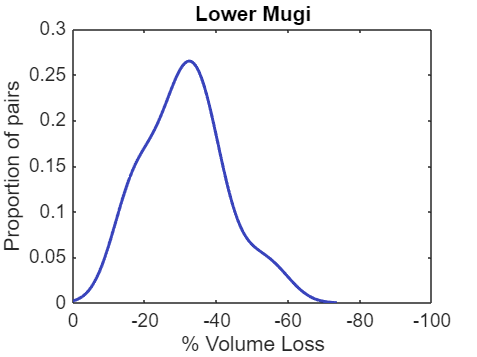


% Plot separate figures 
figure()
plot(LM_f, LM_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Lower Mugi')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

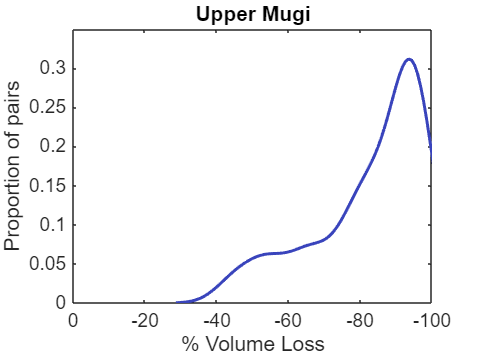


figure()
plot(UM_f, UM_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Upper Mugi')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

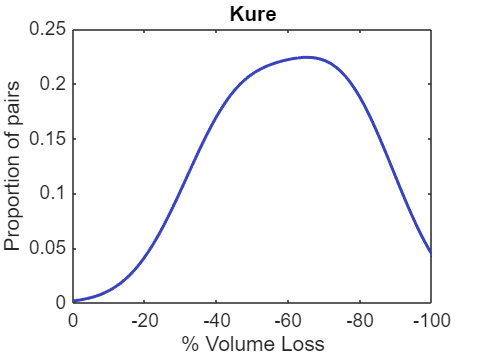


figure()
plot(Ku_f, Ku_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Kure')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

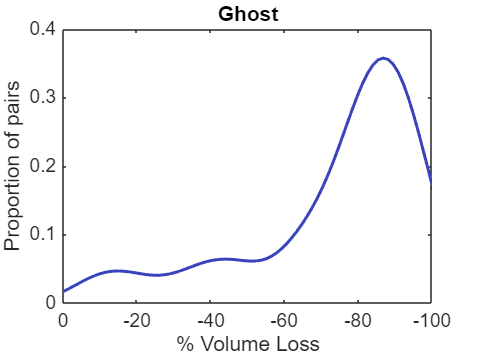


figure()
plot(G_f, G_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Ghost')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

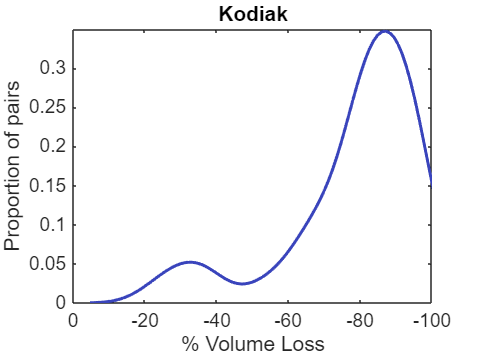


figure()
plot(Ko_f, Ko_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Kodiak')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

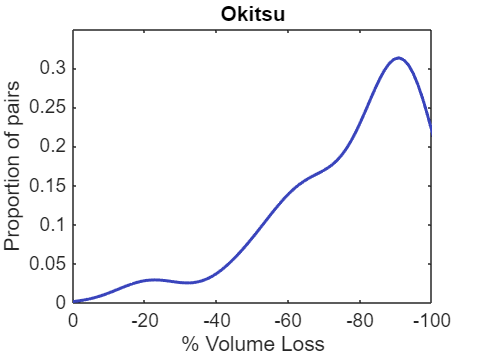


figure()
plot(Ok_f, Ok_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Okitsu')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

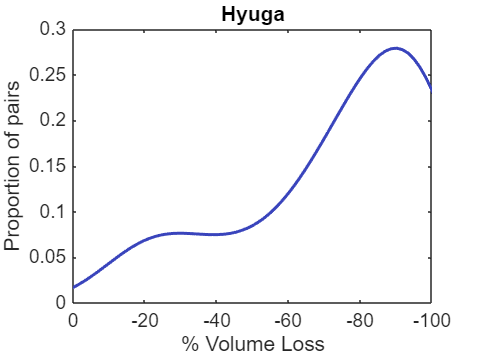


figure()
plot(Hy_f, Hy_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Hyuga')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

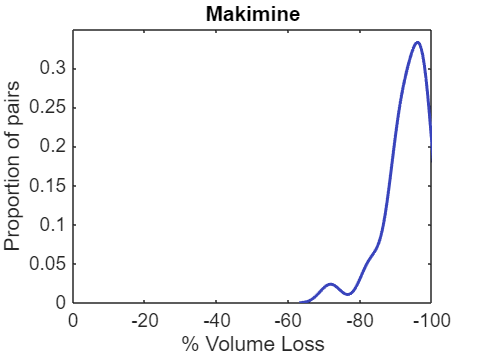


figure()
plot(Ma_f, Ma_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Makimine')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

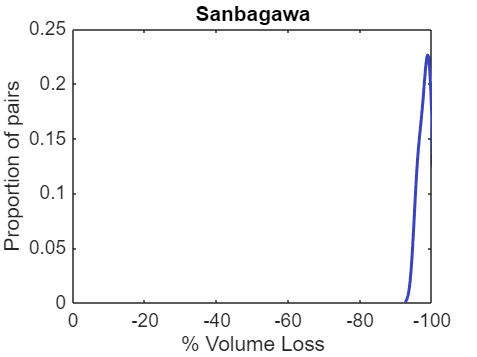


figure()
plot(Sa_f, Sa_ML_n, LineWidth= 1.5, Color= '#3944BC')
xlabel('% Volume Loss')
ylabel('Proportion of pairs')
title('Sanbagawa')
set(gca, 'XDir', 'reverse')
xlim([-100 0])

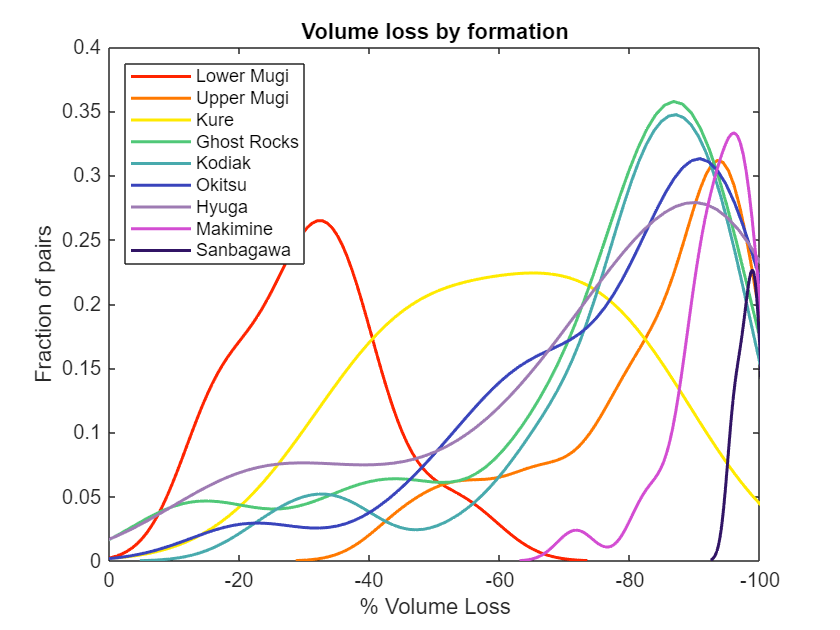

%Stacked Figure
figure()
plot(LM_f, LM_ML_n, LineWidth= 1.5, Color= '#FF2400')
hold on;
plot(UM_f, UM_ML_n, LineWidth= 1.5, Color= '#FF7900')
plot(Ku_f, Ku_ML_n, LineWidth= 1.5, Color= '#FFEA00')
plot(G_f, G_ML_n, LineWidth= 1.5, Color= '#50C878')
plot(Ko_f, Ko_ML_n, LineWidth= 1.5, Color= '#48AAAD')
plot(Ok_f, Ok_ML_n, LineWidth= 1.5, Color= '#3944BC')
plot(Hy_f, Hy_ML_n, LineWidth= 1.5, Color= '#9E7BB3')
plot(Ma_f, Ma_ML_n, LineWidth= 1.5, Color= '#D34DD2')
plot(Sa_f, Sa_ML_n, LineWidth= 1.5, Color= '#311465')
hold off; 
xlabel('% Volume Loss')
ylabel('Fraction of pairs')
title('Volume loss by formation')
legend('Lower Mugi', 'Upper Mugi', 'Kure', 'Ghost Rocks', 'Kodiak', 'Okitsu', 'Hyuga', 'Makimine', ...
    'Sanbagawa', Location='northwest')
set(gca, 'XDir', 'reverse')
xlim([-100 0])